imaqhwinfo("winvideo")

ans = struct with fields:
       AdaptorDllName: 'C:\ProgramData\MATLAB\SupportPackages\R2022a\toolbox\imaq\supportpackages\genericvideo\adaptor\win64\mwwinvideoimaq.dll'
    AdaptorDllVersion: '6.6 (R2022a)'
          AdaptorName: 'winvideo'
            DeviceIDs: {[1]}
           DeviceInfo: [1×1 struct]


vid = videoinput('winvideo','1','MJPG_1024x576')

Summary of Video Input Object Using 'C270 HD WEBCAM'.

   Acquisition Source(s):  input1 is available.

  Acquisition Parameters:  'input1' is the current selected source.
                           10 frames per trigger using the selected source.
                           'MJPG_1024x576' video data to be logged upon START.
                           Grabbing first of every 1 frame(s).
                           Log data to 'memory' on trigger.

      Trigger Parameters:  1 'immediate' trigger(s) on START.

                  Status:  Waiting for START.
                           0 frames acquired since starting.
                           0 frames available for GETDATA.



clc;clear;close all;
vid = videoinput('winvideo','1','MJPG_1024x576');
preview(vid);

disp('按任一鍵開始拍照取像')

按任一鍵開始拍照取像


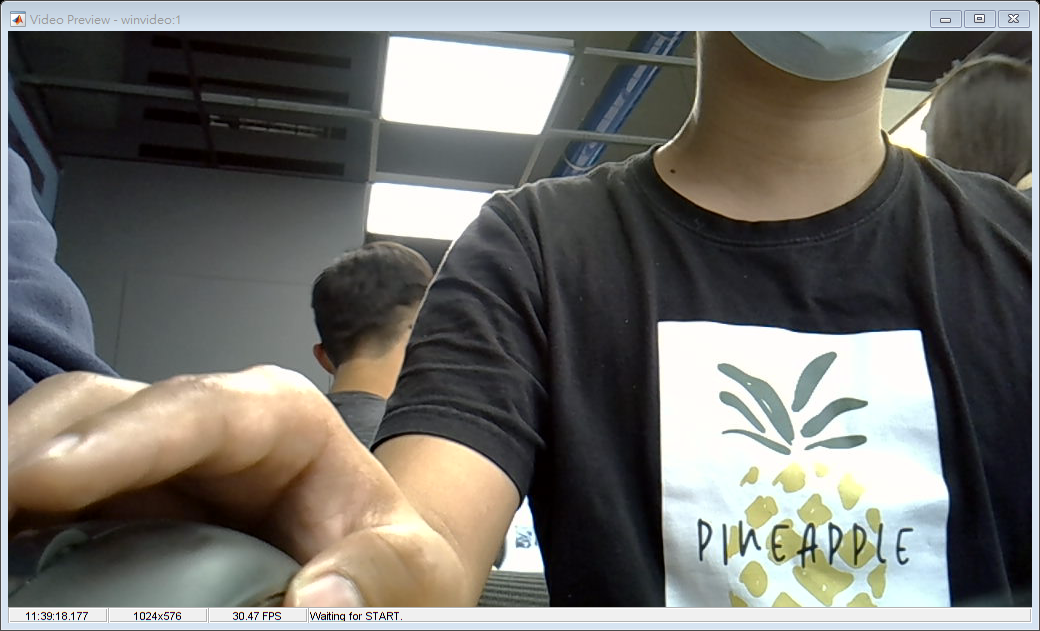

pause

photo = getsnapshot(vid);
subplot(2,4,1);imshow(photo)
image222 = rgb2gray(photo)

image222 = 576×1024 uint8 matrix
   27   25   22   18   16   14   14   14   13   15   18   20   21   21   20   20   21   22   25   26   27   27   27   26   26   26   25   27   29   30   30   29   29   30   30   31   31   31   31   30   30   30   31   31   31   30   28   28   29   29
   28   26   22   19   16   15   14   14   13   15   17   20   21   21   21   20   21   22   24   26   27   27   26   26   25   25   25   26   28   30   29   29   29   30   30   31   31   31   31   30   29   30   30   31   30   30   29   28   29   29
   28   27   24   20   17   15   14   14   13   15   17   19   21   21   21   21   21   22   23   25   25   25   25   25   24   24   24   25   28   29   29   29   29   30   30   31   31   31   30   30   29   30   30   30   30   29   29   28   29   29
   29   28   25   22   19   16   15   14   13   15   17   19   20   21   21   21   21   21   22   23   24   24   24   24   24   23   23   25   27   29   29   28   29   29   30   30   30   30   30   30   29   29   2

subplot(2,4,2);imshow(image222)
image = im2bw (photo,0.3)

image = 576×1024 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

subplot(2,4,3);imshow(image)
J = imcomplement(photo)

J = 576×1024×3 uint8 array
J(:,:,1) =

   232   234   235   239   238   240   239   239   238   236   233   231   232   232   233   233   235   234   231   230   229   229   229   230   230   230   231   229   227   226   226   227   228   227   227   226   226   226   226   227   227   227   226   226   226   227   229   229   227   227   227   226   226   226   226   226   224   224   224   224   224   224   224   224   226   225   224   223   222   221   220   219   220   220   221   221   222   222   222   221   222   221   222   222   222   223   224   225   222   222   222   222   222   222   222   222   223   224   225   225   224   224   225   226   228   228   226   226   226   227   227   227   228   229   230   232   233   235   235   236   238   238   238   239   237   237   238   238   236   236   236   235   235   235   235   235   234   233   233   232   232   233   234   235   233   234   235   236   236   235   235   234   237   236   236   236   235   235   234   234 

subplot(2,4,4);imshow(J)
J=imadjust(photo,[0  1],[0  1],0.1)

J = 576×1024×3 uint8 array
J(:,:,1) =

   200   199   198   193   195   192   193   193   195   197   200   201   200   200   200   200   198   199   201   202   203   203   203   202   202   202   201   203   204   205   205   204   204   204   204   205   205   205   205   204   204   204   205   205   205   204   203   203   204   204   204   205   205   205   205   205   207   207   207   207   207   207   207   207   205   206   207   207   208   208   209   210   209   209   208   208   208   208   208   208   208   208   208   208   208   207   207   206   208   208   208   208   208   208   208   208   207   207   206   206   207   207   206   205   204   204   205   205   205   204   204   204   204   203   202   200   200   198   198   197   195   195   195   193   196   196   195   195   197   197   197   198   198   198   198   198   199   200   200   200   200   200   199   198   200   199   198   197   197   198   198   199   196   197   197   197   198   198   199   199 

subplot(2,4,5);imshow(J)
J=imadjust(image222,[0  1],[0  1],3)

J = 576×1024 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

subplot(2,4,6);imshow(J)

J = imadjust(photo , [0 0.2 0.6 ; 1 0.5 0.9] , [0 0.3 0.7;1 0.4 0.8])

J = 576×1024×3 uint8 array
J(:,:,1) =

    23    21    20    16    17    15    16    16    17    19    22    24    23    23    22    22    20    21    24    25    26    26    26    25    25    25    24    26    28    29    29    28    27    28    28    29    29    29    29    28    28    28    29    29    29    28    26    26    28    28    28    29    29    29    29    29    31    31    31    31    31    31    31    31    29    30    31    32    33    34    35    36    35    35    34    34    33    33    33    34    33    34    33    33    33    32    31    30    33    33    33    33    33    33    33    33    32    31    30    30    31    31    30    29    27    27    29    29    29    28    28    28    27    26    25    23    22    20    20    19    17    17    17    16    18    18    17    17    19    19    19    20    20    20    20    20    21    22    22    23    23    22    21    20    22    21    20    19    19    20    20    21    18    19    19    19    20    20    21    21 

subplot(2,4,7);imshow(J)

J=imadjust(photo,[0  1],[1  0],1)

J = 576×1024×3 uint8 array
J(:,:,1) =

   232   234   235   239   238   240   239   239   238   236   233   231   232   232   233   233   235   234   231   230   229   229   229   230   230   230   231   229   227   226   226   227   228   227   227   226   226   226   226   227   227   227   226   226   226   227   229   229   227   227   227   226   226   226   226   226   224   224   224   224   224   224   224   224   226   225   224   223   222   221   220   219   220   220   221   221   222   222   222   221   222   221   222   222   222   223   224   225   222   222   222   222   222   222   222   222   223   224   225   225   224   224   225   226   228   228   226   226   226   227   227   227   228   229   230   232   233   235   235   236   238   238   238   239   237   237   238   238   236   236   236   235   235   235   235   235   234   233   233   232   232   233   234   235   233   234   235   236   236   235   235   234   237   236   236   236   235   235   234   234 

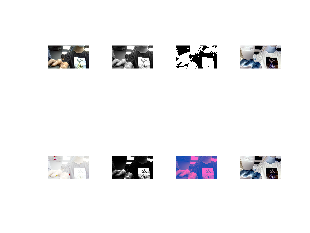

subplot(2,4,8);imshow(J)